Definicion inicial de los parametros para la señal de ejemplo

n=0:1000;% vector de tiempo discreto
n1=0:0.01:1000; % tiempo continuo 
k=n/1001;% vector de frecuencias
xn=sin(2*pi*n*1/4)+sin(2*pi*n*1/8)+sin(2*pi*n*1/32)+sin(2*pi*n*1/128)+sin(2*pi*n*1/512);%discreto
xn1=sin(2*pi*n1*1/4)+sin(2*pi*n1*1/8)+sin(2*pi*n1*1/32)+sin(2*pi*n1*1/128)+sin(2*pi*n1*1/512);%continuo
xk=abs(fft(xn));



se grafica la señal original en discreto continuo y su espectro

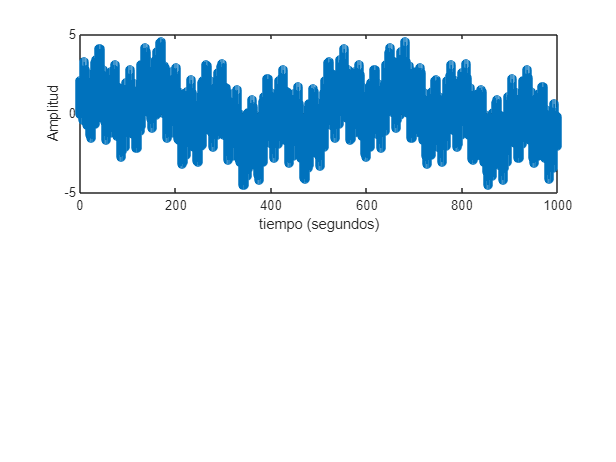

%continuo
subplot(2,1,1);
stem(n1,xn1);
xlabel('tiempo (segundos)')
ylabel('Amplitud')

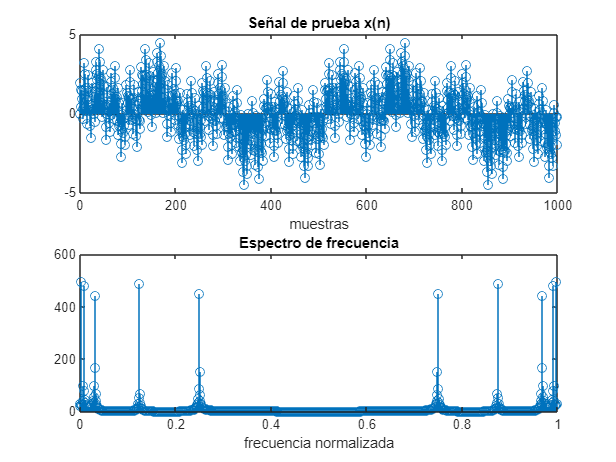


%discreto
figure()
subplot(2,1,1);
stem(n,xn);
xlabel('muestras')
title('Señal de prueba x(n)');
%espectro
subplot(2,1,2);
stem(k,xk);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

se aplican los filtros firr de ventana para esta señal 

pasa bajos 

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


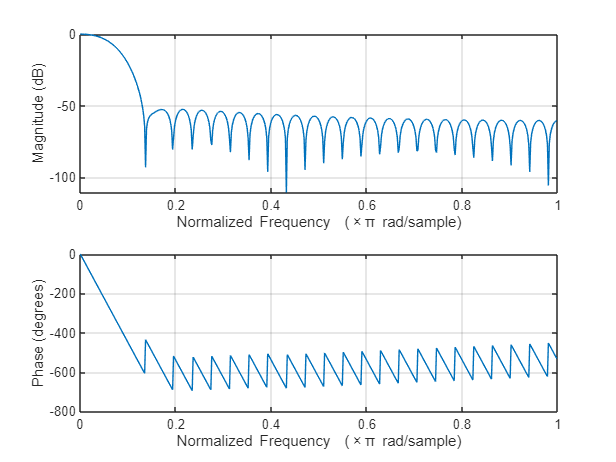

h1n=fir1(50,1/16,"low"); 
figure();
freqz(h1n,1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(h1n,1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

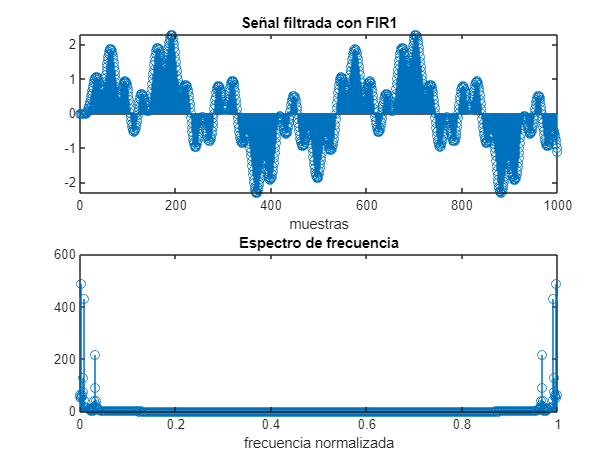

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con FIR1');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

pasa altos 

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


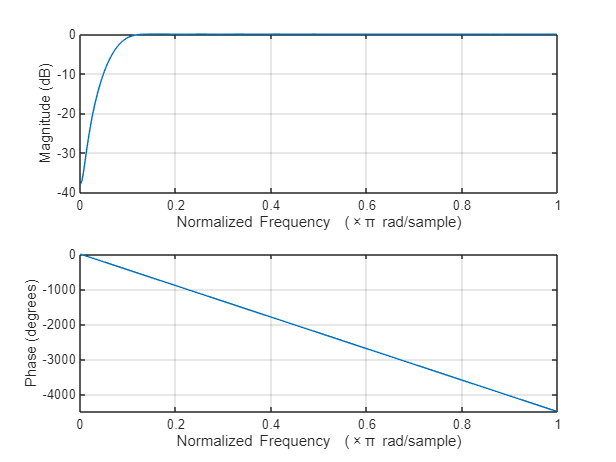

h1n=fir1(50,1/16,"high"); 
figure();
freqz(h1n,1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(h1n,1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

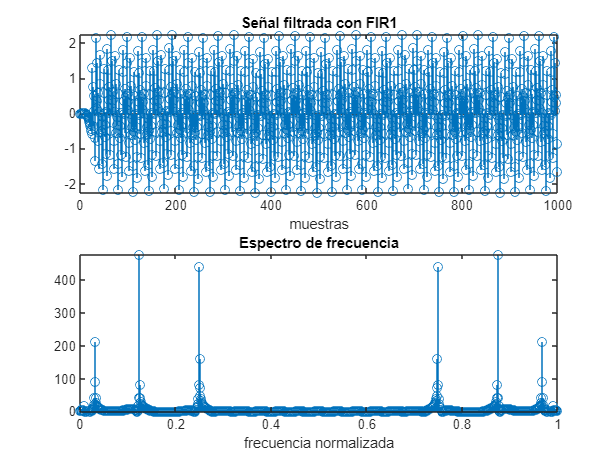

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con FIR1');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

pasa bandas

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


a=[1/55 1/3]

a =     0.0182    0.3333


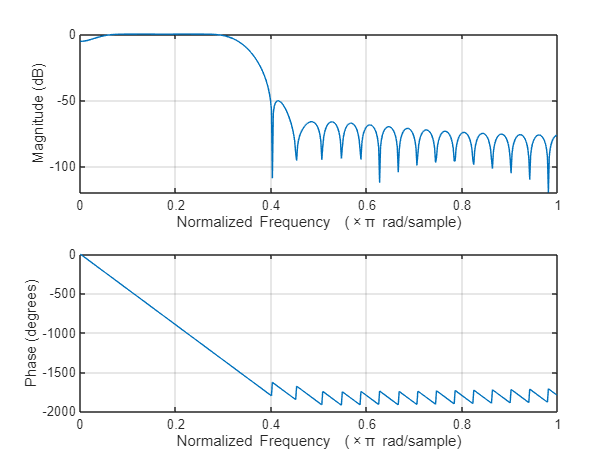

h1n=fir1(50,a,"bandpass"); 
figure();
freqz(h1n,1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(h1n,1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

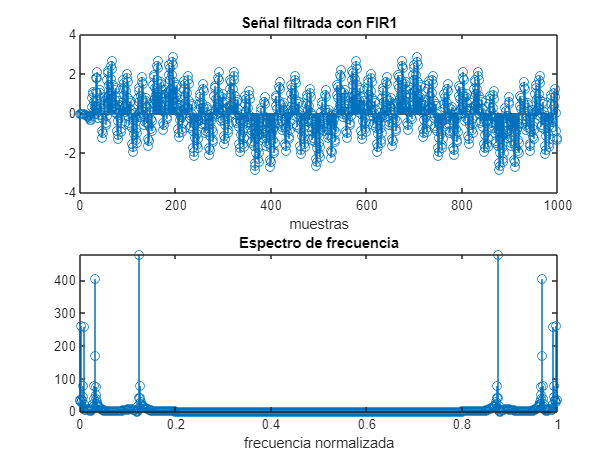

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con FIR1');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

rechaza banda

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


a=[1/55 1/3]

a =     0.0182    0.3333


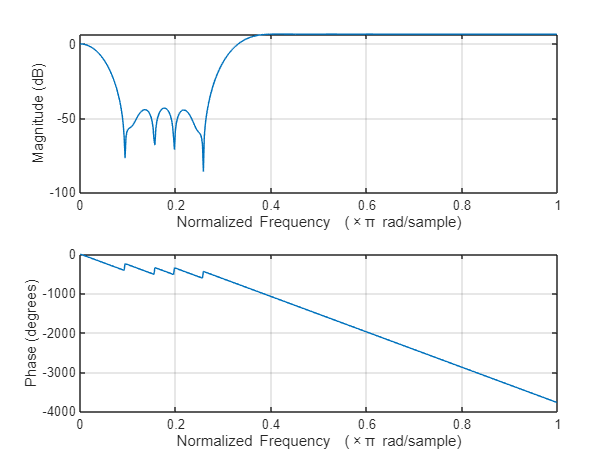

h1n=fir1(50,a,"stop"); 
figure();
freqz(h1n,1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(h1n,1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

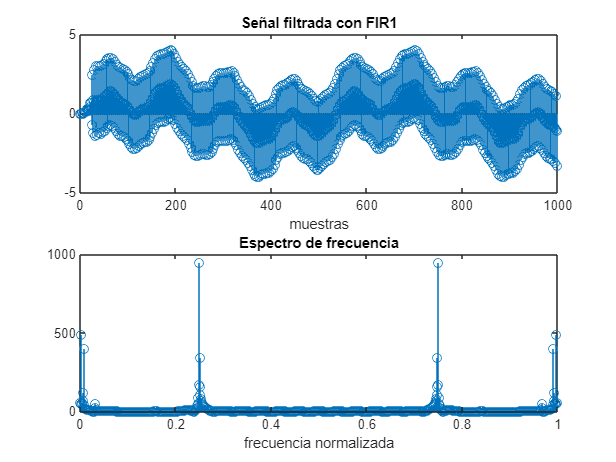

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con FIR1');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

FILTROS IIR

Se crea un filtro pasa-bajos digital utilizando el método de Butterworth. Mediante la función butter se obtienen los coeficientes de la función de transferencia del filtro.

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


Observe las unidades de frecuencia que utiliza matlab

[b1,a1]=butter(3,1/16);

A continuación se grafica la respuesta en frecuencia del filtro mediante el comando freqz. Como se trata de un filtro iir, note que se tienen valores diferentes de 1 para el denominador de la función de transferencia

Haciendo zoom sobre la figura, trate de ubicar el punto más cercano a la frecuencia de corte (ganancia -3 dB)

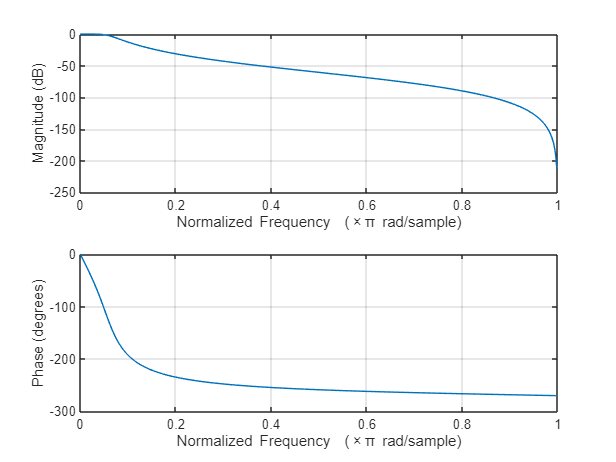

figure();
freqz(b1,a1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(b1,a1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

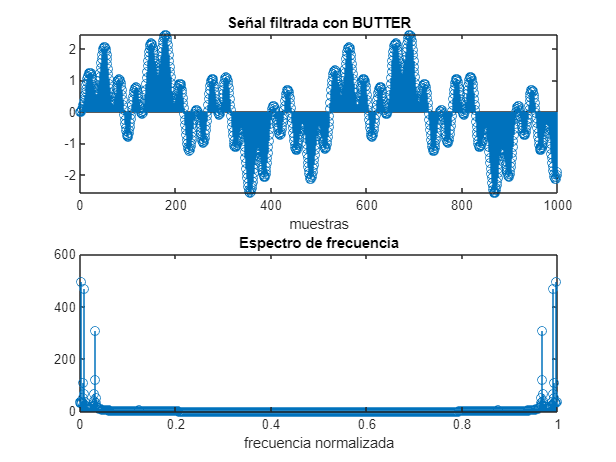

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con BUTTER');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

## Pasa altos 

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


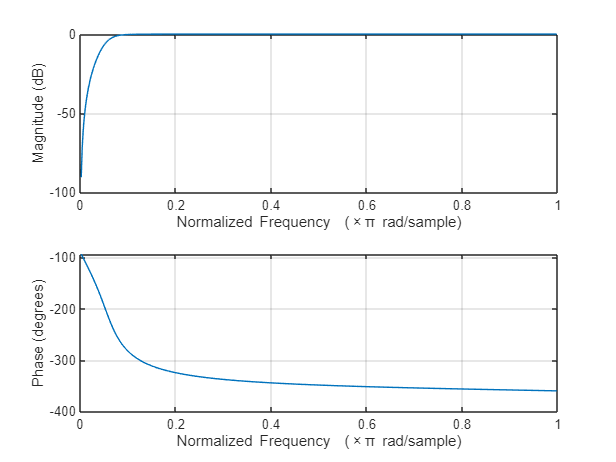

[b1,a1]=butter(3,1/16,"high");
figure();
freqz(b1,a1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(b1,a1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

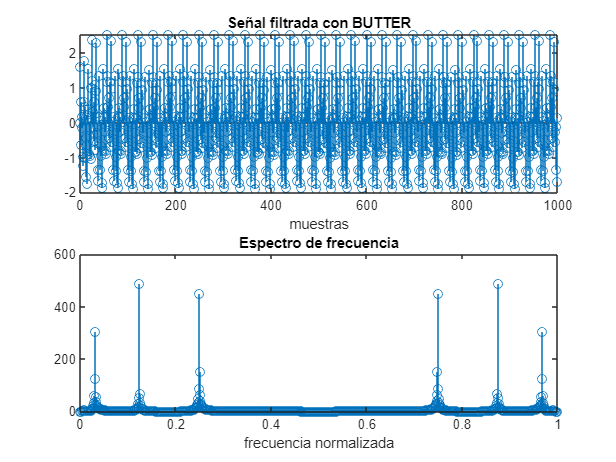

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con BUTTER');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

## PASA BANDA

a=[1/55 1/3]

a =     0.0182    0.3333


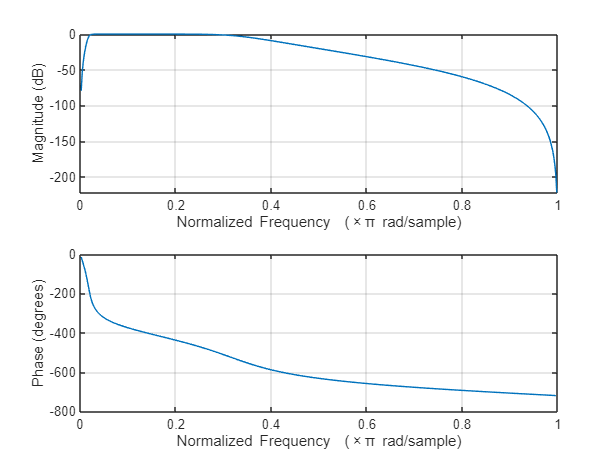

[b1,a1]=butter(4,a,"bandpass");
figure();
freqz(b1,a1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(b1,a1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

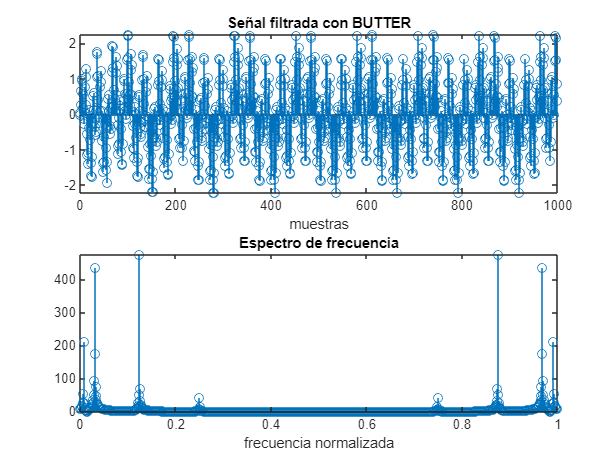

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con BUTTER');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

## RECHAZA-BANDA

a=[1/55 1/3]

a =     0.0182    0.3333


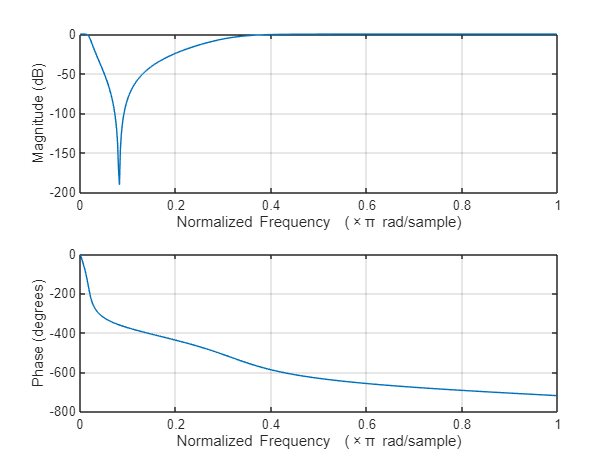

[b1,a1]=butter(4,a,"stop");
figure();
freqz(b1,a1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(b1,a1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

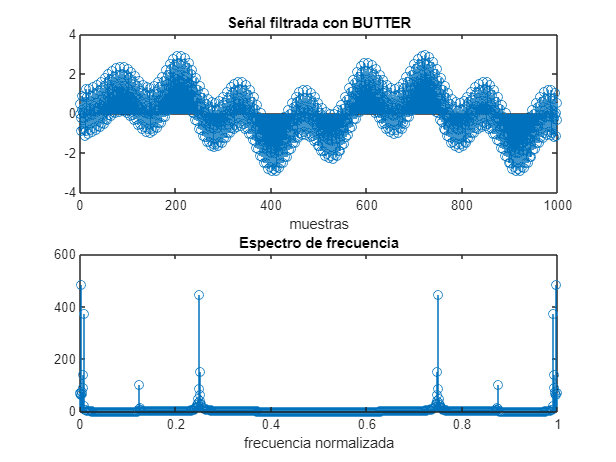

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con BUTTER');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');